## Shape functiton for a rectangular a x gamma*a QUAD element

Shape functions for rectangular elements are product of Lagrange interpolations in the two coordinate directions. 

syms a gamma x y real

N_1=1/4 * (1 - (2 * x)/a) * (1 - (2 * y)/(a * gamma))

$$N\_1 = \left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)$$

N_2=1/4 * (1 + (2 * x)/a) * (1 - (2 * y)/(a * gamma))

$$N\_2 = -\left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)$$

N_3=1/4 * (1 + (2 * x)/a) * (1 + (2 * y)/(a * gamma))

$$N\_3 = \left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)$$

N_4=1/4 * (1 - (2 * x)/a) * (1 + (2 * y)/(a * gamma))

$$N\_4 = -\left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)$$

%check alpha =3, gamma=2/3

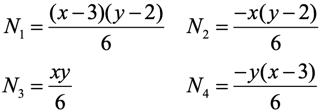

%N_1_check=subs(4*N_1,[x y], [x+(a/2) y+((a*gamma)/2)])
N_1_check=expand(subs(4*N_1,[a gamma], [6 4/6]))

$$N\_1\_check = \frac{x\,y}{6}-\frac{y}{2}-\frac{x}{3}+1$$

N1_course=expand((x-3)*(y-2)/6)

$$N1\_course = \frac{x\,y}{6}-\frac{y}{2}-\frac{x}{3}+1$$

syms x3 y3 real
A=x3*y3

$$A = x_{3}\,y_{3}$$

N1_course=expand((x-x3)*(y-y3)/A)

$$N1\_course = \frac{x\,y}{x_{3}\,y_{3}}-\frac{y}{y_{3}}-\frac{x}{x_{3}}+1$$

N1_course=subs(N1_course,[x3 y3], [a/2 gamma*a/2])

$$N1\_course = \frac{4\,x\,y}{a^{2}\,\gamma }-\frac{2\,y}{a\,\gamma }-\frac{2\,x}{a}+1$$

4*expand(N_1)

$$ans = \frac{4\,x\,y}{a^{2}\,\gamma }-\frac{2\,y}{a\,\gamma }-\frac{2\,x}{a}+1$$

N_2_check=expand(subs(4*N_2,[a gamma], [6 4/6]))

$$N\_2\_check = \frac{x}{3}-\frac{y}{2}-\frac{x\,y}{6}+1$$

N_3_check=expand(subs(4*N_3,[a gamma], [6 4/6]))

$$N\_3\_check = \frac{x}{3}+\frac{y}{2}+\frac{x\,y}{6}+1$$

N_4_check=expand(subs(4*N_4,[a gamma], [6 4/6]))

$$N\_4\_check = \frac{y}{2}-\frac{x}{3}-\frac{x\,y}{6}+1$$